# 1 Light it up

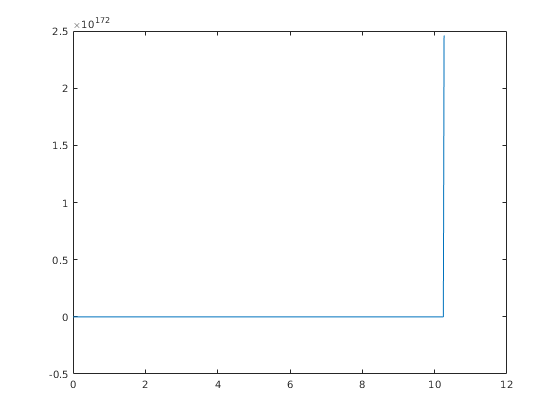

f = @(t,r) 100*r.^2 - r.^3;
[t,r] = eulerivp(f,[0,20],.001,1000);
plot(t,r)

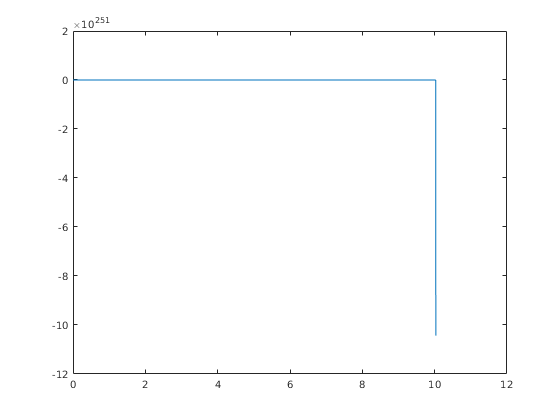

[t,r] = eulerivp(f,[0,20],.001,10000);
plot(t,r)

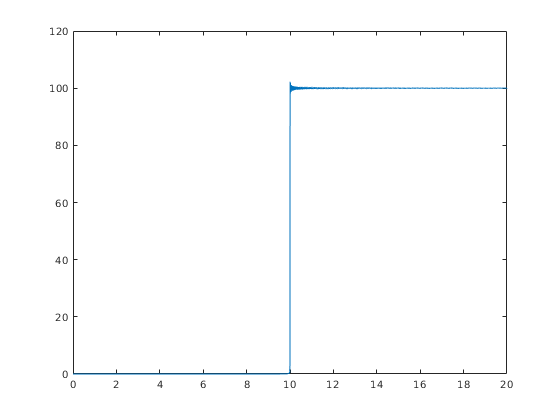

[t,r] = eulerivp(f,[0,20],.001,100000);
plot(t,r)

# 2 Runge-Kutta

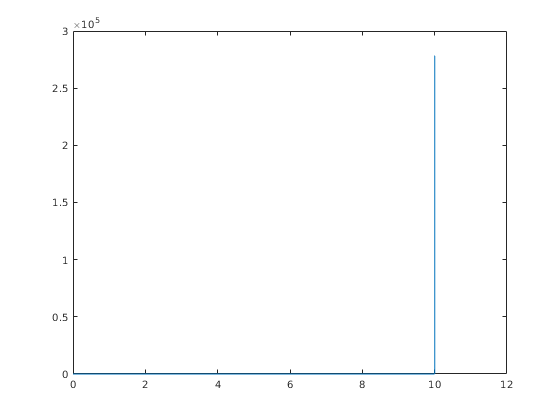

[t,r] = rk4(f,[0,20],.001,1e5/4);
plot(t,r)

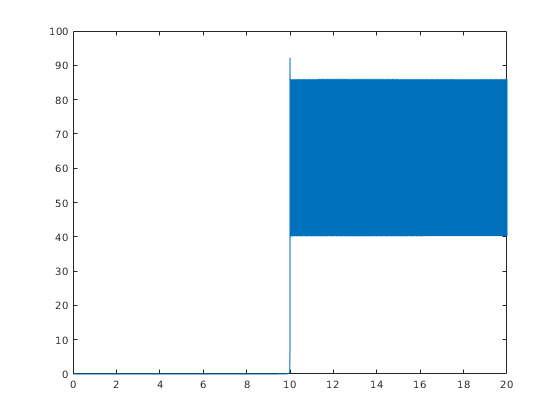

[t,r] = rk4(f,[0,20],.001,1e5/2);
plot(t,r)

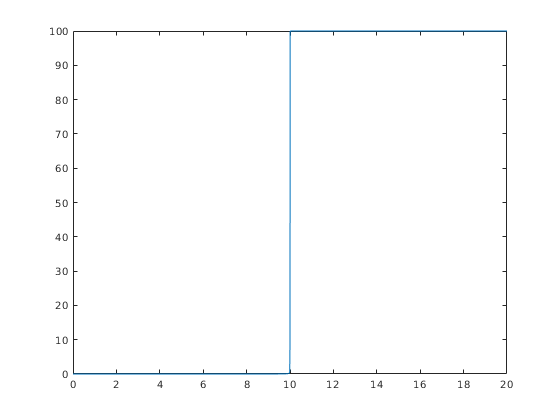

[t,r] = rk4(f,[0,20],.001,1e5);
plot(t,r)

# 3 Adapt

[t,r] = rk23(f,[0,20],.001,1e-3);
numsteps = length(t)-1

numsteps =        39430


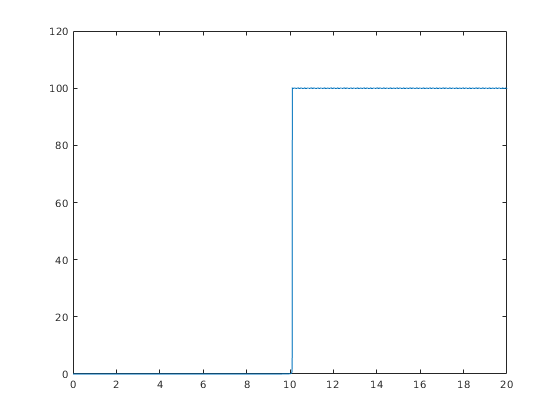

plot(t,r)

[t,r] = rk23(f,[0,20],.001,1e-5);
numsteps = length(t)-1

numsteps =        39842


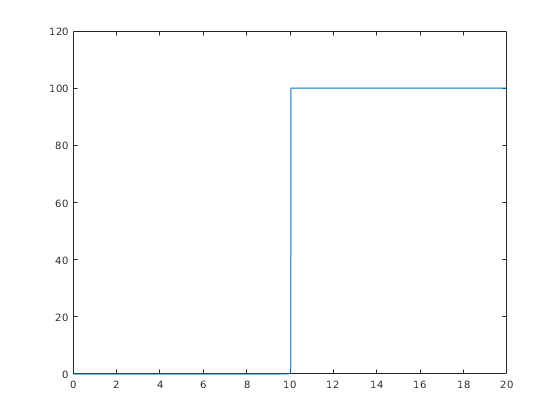

plot(t,r)

[t,r] = rk23(f,[0,20],.001,1e-7);
numsteps = length(t)-1

numsteps =        40728


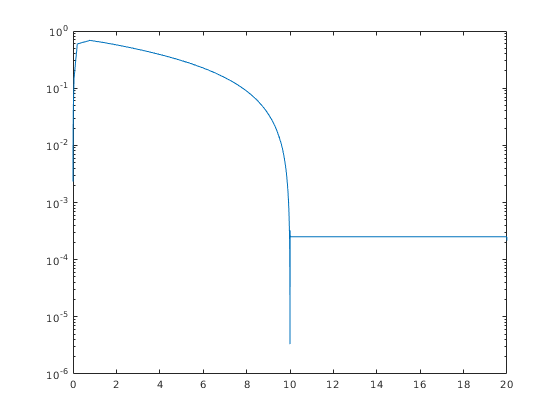

semilogy(t(1:end-1),diff(t))

# 4. Implicit

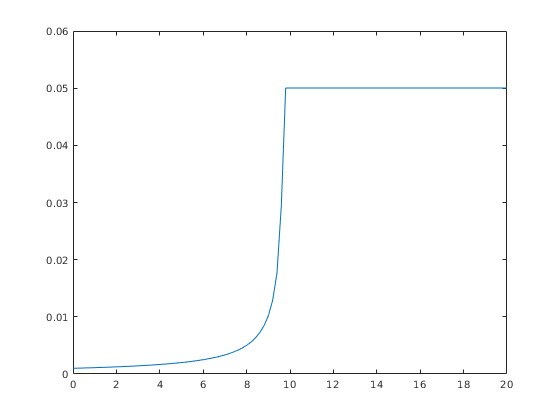

warning off
[t,r] = am2(f,[0,20],.001,100);
plot(t,r)

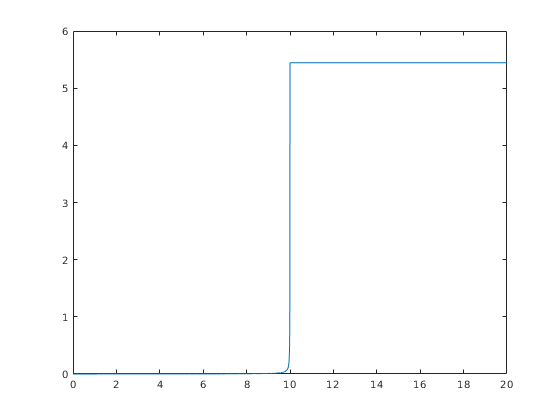

[t,r] = am2(f,[0,20],.001,10000);
plot(t,r)

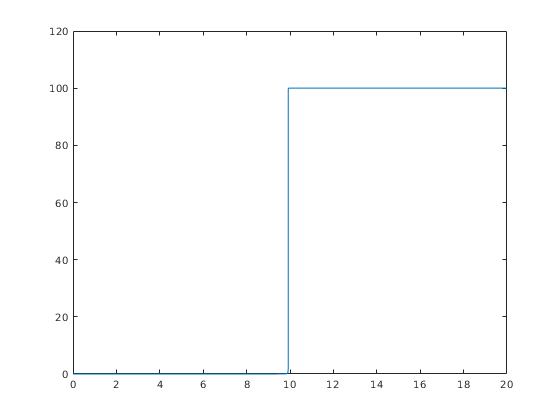

[t,r] = ode15s(f,[0,20],.001);
plot(t,r)

numsteps = length(t)-1

numsteps =     97


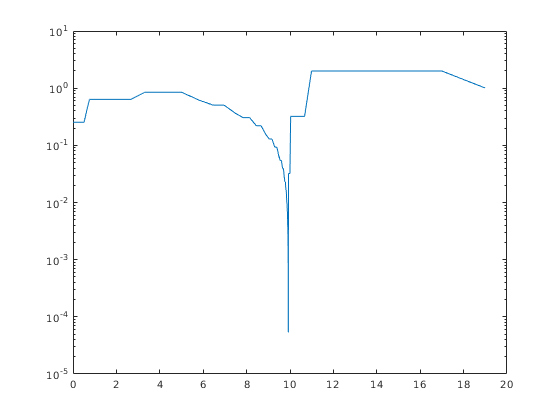

semilogy(t(1:end-1),diff(t))